# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 800; % # sample points
A = 21; % Magnitude/Amplitude of droplet
c1 = 0.001264379882813;
c2 = 0.016807519531250;
tfinal = 10^5; % final time >> 1
xMax = 80; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 10;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

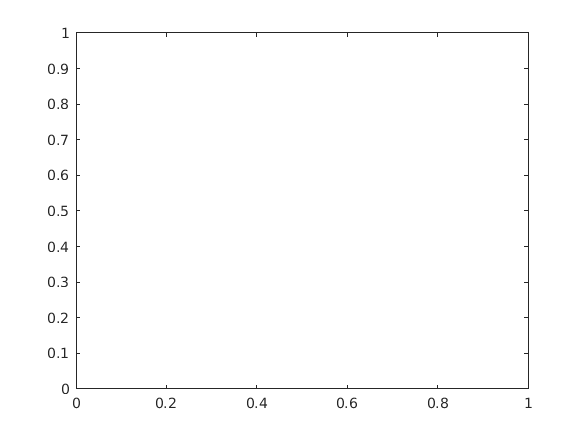

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          173.673         
     1            2          173.673         initial simplex
     2            4          169.009         expand
     3            6          149.172         expand
     4            8          79.3554         expand
     5           10          31.5481         reflect
     6           12          31.5479         contract inside
     7           14          16.4522         contract inside
     8           16          16.4522         contract inside
     9           18          16.4244         contract outside
    10           20          16.4244         contract inside
    11           22          16.4244         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



[tSpan,D1,D2,X,H0B,myObjective_Possition,conds_SolB,...
    fvalB,exitflagB,outputB,historyB,h_SolB,H_SolB]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,h_target);

**Figures**

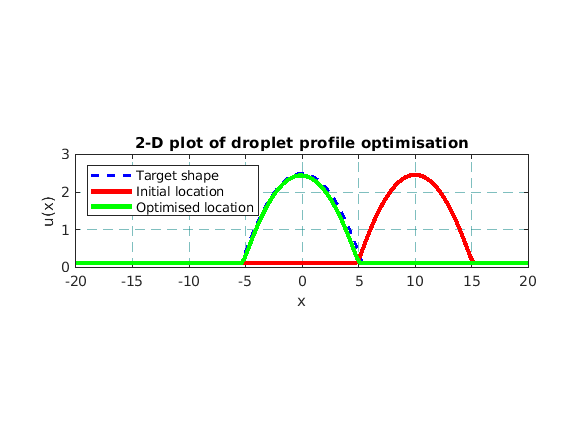

figure;
plot(X,h_target,'b--','linewidth',2);
title('2-D plot of droplet profile optimisation')
xlabel('x')
ylabel('u(x)')
hold on
plot(X,H0B,'r-','linewidth',3);
xlim([-20 20]);
ylim([0 3]);
grid on

ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

pbaspect([4 1 1]);
plot(X,H_SolB,'g-','linewidth',3);
legend('Target shape','Initial location','Optimised location','Location','northwest');
hold off

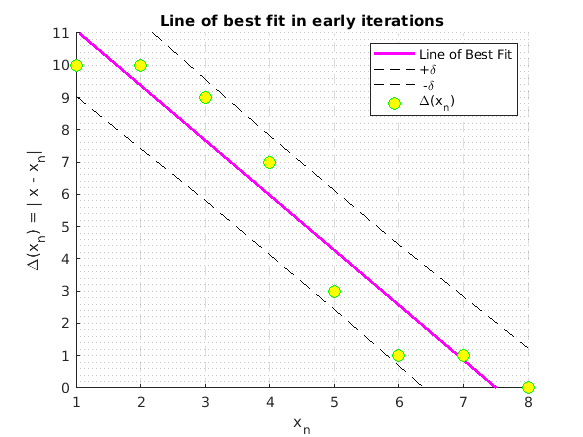

n = size(historyB);
n = n(1);
dataH = abs(historyB(1:8,1))';
dataHi = abs(historyB(:,1))';
lineH = 1:1:8;
lineHi = 1:1:n;
[p,S,mu] = polyfit(lineH,dataH,1);
[pH,delta] = polyval(p,lineH,S,mu);

xi = linspace(1, n, 100); 
yi = interp1(lineHi, dataHi, xi, 'spline', 'extrap');

figure;
hold on

plot(lineH,pH,'-',...
    'Color','m',...
    'LineWidth',2);
plot(lineH,pH-1.4*delta,'k--');
plot(lineH,pH+1.4*delta,'k--');
plot(lineH,dataH,'o',...
    'MarkerSize',8,...
    'MarkerEdgeColor',[0 1 0],...
    'MarkerFaceColor',[1 1 0],...
    'LineWidth',1);

title('Line of best fit in early iterations');
ylabel('\Delta(x_n) = | x - x_n|');
xlabel('x_n');
legend('Line of Best Fit','+\delta',' -\delta','\Delta(x_n)');

set(gca,'xtick',0:1:100);
set(gca,'ytick',0:1:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 8]);
ylim([0 x0+1]);

hold off

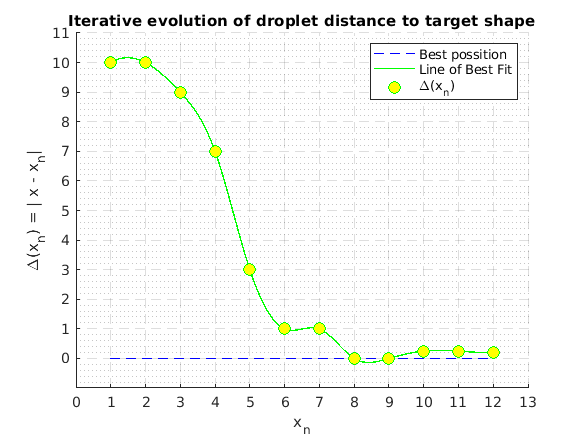


figure;
hold on

line0 = zeros(size(xi));
plot(xi,line0,'k--');

plot(xi, yi,'k:',...
    'LineWidth',1);
plot(lineHi,dataHi,'o',...
    'MarkerSize',8,...
    'MarkerEdgeColor',[0 1 0],...
    'MarkerFaceColor',[1 1 0],...
    'LineWidth',1);

title('Iterative evolution of droplet distance to target shape');
ylabel('\Delta(x_n) = | x - x_n|');
xlabel('x_n');
legend('Best possition','Line of Best Fit','\Delta(x_n)');

set(gca,'xtick',0:1:100);
set(gca,'ytick',0:1:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([0 n+1]);
ylim([-.2 x0+1]);
box off

hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis